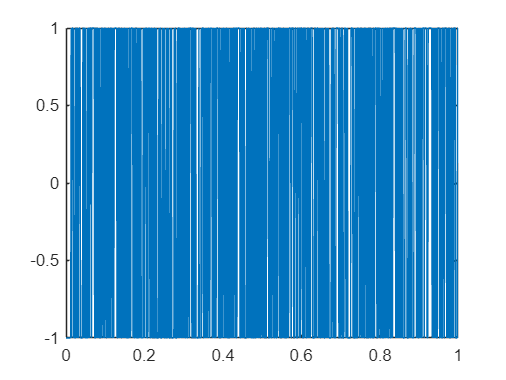

fs = 1000;          % 采样频率1000Hz
t = 0:1/fs:1;       % 时间向量（1秒，共1001个点）
% 1. sin
f1 = 50; f2 = 120;  % 信号频率成分
x = sin(2*pi*f1*t) + 0.5*sin(2*pi*f2*t) + 0.3*randn(size(t));  % 带噪声信号
% % 2. 矩形窗
% for i = 1:length(t)
%     if t(i) < 0.3
%        x(i) = 1;
%     else 
%        x(i) = 0;
%     end
% end
% % 3. PRBS
n = 13;   % 如果寄存器给的少，将能够看到明显的周期，这不是我们想要的效果。给的多的话会近似随机序列
          % 偶数比奇数个随机效果差一点。不知道为啥
          % 部分阶数会在同一个周期内出现重复的小周期  非原本多项式  要正确设置异或门的位置
x = PRBS(t,n,1);
plot(t,x)

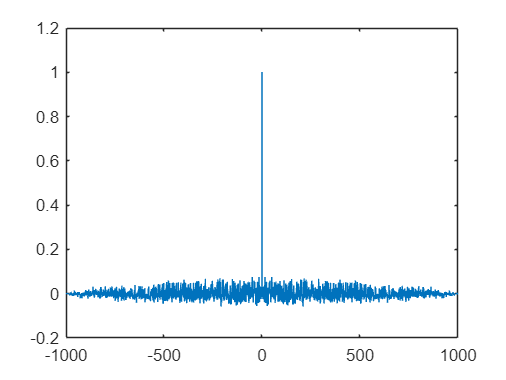

%% 实验证明 用stairs处理后的频谱和不处理的频谱几乎一模一样  不同在高频段细节更多
%% 这就跟6个点可以复现一个sin函数的频率一样
% [xo,yo]=stairs(t,x);
% plot(xo,yo)
% t = xo;  % 注意变换后fs = 2000;
% x = yo;

% a = 1;
% Out=genPRBS(n,a,length(t));
% plot(t,Out)


[r, lags] = xcorr(x); 
plot(lags,r/fs)

% Identification of a system impulse response

clc; close all; clear all;

R = 100e3;          	% 100k ohm
C = 1e-6;             	% 1 uf
tc = R*C;               % Time constant

% Generate M-sequence
n=5;
a=2;                % Level of the PRBS   1 --- -a   0 --- +a
Del = 15e-3;      	% Clock pulse period
N=2^n-1;           	% Period of M sequence
L=2*N;             

% Generate M-sequence using the 'genPRBS' function
Out = genPRBS(n,a,L);

% Generate the response y(t) of the system
s = tf('s'); 
G = 1/(tc*s+1)

G =
 
      1
  ---------
  0.1 s + 1
 
连续时间传递函数。
模型属性


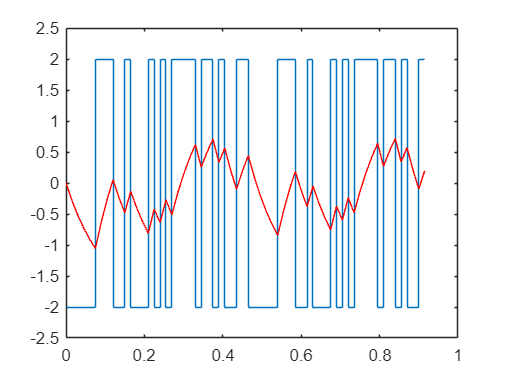

ft = L*Del;
time = 0:Del:ft-Del;
y  = lsim(G, Out, time);

% Plot the input and output of the system
figure
stairs(time,Out);
axis([0 1.0 -2.5 2.5]);
hold on
plot(time,y,'r');
hold off


% Compute Rxy(i*Del)
temp = 0.0;
Rxy = [];
iDelv=[];
for i=1:N
    tau=i-1;
    iDelv=[iDelv;tau*Del];
       for j=1:N
           temp=temp+sign(Out(j))*y(j+tau);
       end
Rxyi = (a/N)*temp;
temp=0.0;
Rxy = [Rxy;  tau  Rxyi];
end

% Compute ghat & g
Lr = length(Rxy);
C = -Rxy(Lr, 2);
S = (N+1)*a^2*Del/N;
Rxy_iDel = Rxy(:,2);
ghat=(Rxy_iDel+ C )/S;
ghat(1)=2*ghat(1);
g = 10*exp(-10.*iDelv);     % Impulse response of G(s)
Result = [Rxy  ghat   g];

disp(' -------------------------------------------');

 -------------------------------------------


disp(' i      Rxy(iDel)     ghat          g');

 i      Rxy(iDel)     ghat          g


disp(' -------------------------------------------');

 -------------------------------------------


disp(num2str(Result));

 0   -0.0319183      2.86143           10
 1     0.529696      10.4984      8.60708
 2      0.43794      9.01697      7.40818
 3     0.358965      7.74186      6.37628
 4     0.290991      6.64436      5.48812
 5     0.232485      5.69973      4.72367
 6     0.182129      4.88668       4.0657
 7     0.138787      4.18689      3.49938
 8     0.101482      3.58456      3.01194
 9    0.0693728      3.06614       2.5924
10    0.0417366      2.61993       2.2313
11    0.0179498      2.23588       1.9205
12   -0.0025236      1.90531      1.65299
13   -0.0201452       1.6208      1.42274
14   -0.0353123      1.37591      1.22456
15   -0.0483668      1.16514      1.05399
16   -0.0596028     0.983723      0.90718
17   -0.0692738     0.827577     0.780817
18   -0.0775977     0.693181     0.672055
19   -0.0847621     0.577505     0.578443
20   -0.0909286     0.477942     0.497871
21   -0.0962361     0.392248     0.428521
22    -0.100804      0.31849     0.368832
23    -0.104736     0.255006     0

disp(' -------------------------------------------');

 -------------------------------------------


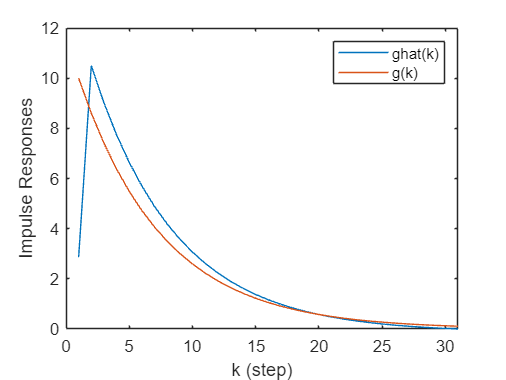


% Display the results
plot(1:Lr,Result(:,3:4)); 
xlabel('k (step)'); ylabel('Impulse Responses'); legend('ghat(k)','g(k)');

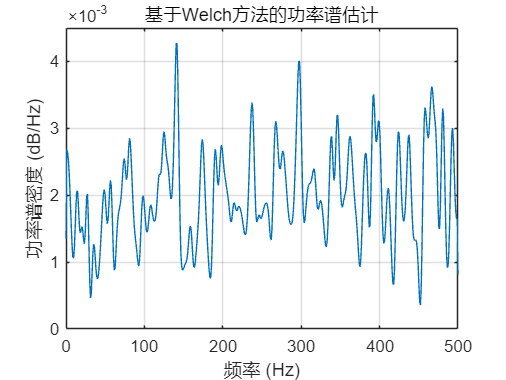

% 配置参数
window = hann(256);  % 汉宁窗，分段长度256
noverlap = 128;      % 重叠128点（50%）
nfft = 1024;         % FFT点数（补零至1024，提高绘图精度）

% 调用pwelch
[P, f] = pwelch(x, window, noverlap, nfft, fs);
  
figure;
plot(f, (P));  % 转换为dB（10log10(功率谱密度)）
xlabel('频率 (Hz)');
ylabel('功率谱密度 (dB/Hz)');
title('基于Welch方法的功率谱估计');
grid on;
xlim([0 fs/2]);  % 实信号仅需显示0至fs/2的正频率

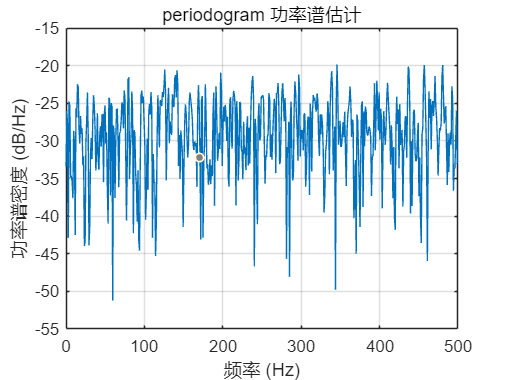

% 配置参数（可加窗改善旁瓣，这里用汉宁窗对比）
window = hann(length(x));  % 窗长等于信号长度（避免分段）
nfft = 1024;               % FFT点数

% 调用periodogram
[P_periodo, f_periodo] = periodogram(x, window, nfft, fs);

figure;

plot(f_periodo, 10*log10(P_periodo));
xlabel('频率 (Hz)'); ylabel('功率谱密度 (dB/Hz)');
title('periodogram 功率谱估计');
grid on; xlim([0 fs/2]); 

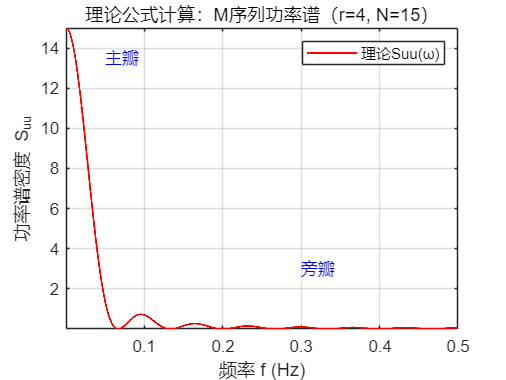

% 功能：根据理论公式计算并绘制M序列功率谱密度Suu(ω)
% 公式：Suu(ω) = (1/N) * | sin(ω*N*Tc/2) / sin(ω*Tc/2) |^2


%% 1. 参数定义
r = 4;              % 移位寄存器位数
N = 2^r - 1;        % M序列周期（N=15 for r=4）
Tc = 1;             % 时钟周期（采样间隔）
omega_max = 2*pi*0.5/Tc;  % 最大角频率（对应奈奎斯特频率Fs/2，Fs=1/Tc）
omega = linspace(1e-6, omega_max, 10000);  % 角频率向量（避免ω=0除零）

%% 2. 理论公式计算（核心）
% 分子：sin(ω*N*Tc/2)
numerator = sin(omega * N * Tc / 2);
% 分母：sin(ω*Tc/2)
denominator = sin(omega * Tc / 2);
% 处理奇点（ω→0时，sin(aω)/sin(bω)≈a/b，此处a=N*Tc/2，b=Tc/2→比值≈N）
ratio = numerator ./ denominator;
% 代入公式计算Suu(ω)
Suu_theo = (1/N) * (abs(ratio)).^2;

%% 3. 转换为频率轴（更直观，f=ω/(2π)）
f = omega / (2*pi);  % 频率（Hz）

%% 4. 绘图：理论功率谱
figure('Name','M序列理论功率谱Suu(ω)');
plot(f, Suu_theo, 'r-', 'LineWidth', 1.2);
grid on; hold on;
xlabel('频率 f (Hz)');
ylabel('功率谱密度 S_{uu}');
title(['理论公式计算：M序列功率谱（r=', num2str(r), ', N=', num2str(N), '）']);
legend('理论Suu(ω)');
axis tight;

% 标注主瓣和旁瓣
text(0.05, max(Suu_theo)*0.9, '主瓣', 'Color', 'b');
text(0.3, max(Suu_theo)*0.2, '旁瓣', 'Color', 'b');

function Out = PRBS(t,n,a)
% a: the altitude of M-sequence, 
% t为生成的时间一共多长
% n用来控制一个PRBS序列的周期长度  一个周期＝2^n-1
% Generate a PRBS signal
% 1. 自相关性尽可能为δ函数（低相关性）。  2. 尽可能均匀分布(接近白噪声）  3. 但又要可被重复实现 
% n=4;                                % the number of registers
% L=15+1;                             % the length of M-sequence to be required   越长越接近白噪声
L = length(t);

for i = 1:n  Reg(i) = 1; end        % Initialize n registers  位移寄存器全1
Out(1)=-a;

for i=2:L
        temp=Reg(1);
        % 注意反馈抽头 可用GPT帮忙写
        % 抽头为第4、5、6、8级，异或结果反馈到第1级  仅适用于n = 8的情况
        % Reg(1) = xor(xor(xor(Reg(4), Reg(5)), Reg(6)), Reg(8)); 
        %% n = 13
        Reg(1) = xor(xor(xor(Reg(1), Reg(3)), Reg(4)), Reg(13));
        %%  仅适用于n= 4  情况
        % Reg(1)=xor(Reg(n-1),Reg(n));  % Modulo 2 adder   第一个寄存器 
        j=2;
        while j<=n                  % Registers shift                
             temp1=Reg(j);
             Reg(j)=temp;
             j=j+1;
             temp=temp1;
        end        
        Out(i)=Reg(n);
        if (Reg(n)==1)  Out(i) =-a; end
        if (Reg(n)==0)  Out(i)=a; end
end   

% stairs(Out); axis([1 L -0.5 1.5]);  % Plot the PRBS signal

end


function Out=genPRBS(n,a,L)    
% Generate a PRBS signal
% Parameters are 
%    n: the number of registers, 
%    a: the altitude of M-sequence, 
%  del: the clock pulse period, 
%    L: the length of M-sequence to be required 
% Make Out be empty for storing binary sequence
Out = [];      
% Initialize  n registers
for i = 1:n  Reg(i) = 1; end
Out(1)=-a;
for i=2:L
        Rs=Reg(1);
        Reg(1)= xor(Reg(n-2),Reg(n));   % Modulo 2 adder
        j=2;
        while j<=n                      % Registers shift                
             Rs1=Reg(j);
             Reg(j)=Rs;
             j=j+1;
             Rs=Rs1;
        end        
        if (Reg(n)==1)  Out(i) =-a; end
        if (Reg(n)==0)  Out(i)=a; end
end   
end